# Vehicle modeling from driving data

If you do not prepare your own driving data or trajectory for testing the MPC's performance, you can run it as is.

## Creation of driving data

When Manual_Trajectory_Generator.slx opens, run it to adjust the rudder angle and create driving data.

warning('off', 'all')

% It is also possible to create driving data using simulink by removing the following comments.
%model_name = 'Manual_Trajectory_Generator';
%open_system(model_name);
%drive_data = getElement(out.logsout, 'y').Values;
load('drive_data.mat')

## Create a state-space model of the vehicle, sys_ss, from driving data

ts = get_TimeStep('sim_data_vehicle.sldd');

% state
px_result = drive_data.px.Data;
py_result = drive_data.py.Data;
theta_result = drive_data.theta.Data;
r_result = drive_data.r.Data;
beta_result = drive_data.beta.Data;
V_result = drive_data.V.Data;

% input δ
delta = drive_data.delta.Data;


result_mat = [px_result, py_result, theta_result, r_result, beta_result, V_result];

% Data set initialization
data_set_list = {};

% How many data are counted as one set
data_num = 5;

% dataset Creation
i0 = 1;

for i = 1:length(delta)/data_num - 1
    % Waypoints to convert coordinates
    ref_point = i0 + (i-1) * data_num;
    state_data = zeros(data_num,6);

    % State of waypoints to be coordinate transformed
    referenceState = result_mat(ref_point, :);

    % Convert and store the states to be included in a single data set
    for j = 1:data_num
        state = result_mat(ref_point + j - i0, :);
        state_data(j,:) = transformState(referenceState, state).';
    end

    % Stores δ corresponding to the data set
    delta_data = delta(ref_point : ref_point + data_num - 1);
    % Converted to iddata type
    data_set_list{i} = iddata(state_data(:,2:4), delta_data, ts);
end

% Merge datasets
data_set = merge(data_set_list{:});

na = [[1, 1, 1];
      [1, 1, 1];
      [1, 1, 1]];
nb = [1;1;1];
nk = [1;1;1];
sys_arx = arx(data_set, [na nb nk]);
sys_ss = ss(sys_arx);

## Create state space model dlsys1 using equivalent two-wheel model

x0 = [0; 0; 0; 0; 0; 10];
yNum_MPC = 6;

% mass
m_val = 2000;
% Length from vehicle center of gravity to front and rear wheels
l_f_val = 1.4;
l_r_val = 1.6;
% Yaw pole inertia
I_val = 4000;
% Equivalent cornering power
K_f_val = 12e3;
K_r_val = 11e3;
div_min = 1e-3;



xl0 = [0; 0];
ul0 = 0;
mdl0 = 0;

V_const = 3;

Ald = [1, V_const*ts;
        0, 1];
Bld = [0, 0;
       V_const/(l_f_val + l_r_val)*ts, -1*ts];
Cld = [1, 0;
       0, 1];
Dld = [0, 0; 
       0, 0];
dlsys1 = ss(Ald, Bld, Cld, Dld, ts);

l_normal_input_names = {'delta', 'md'};
l_state_names = {'py', 'theta'};
l_output_names = {'py', 'theta'};
dlsys1.InputName = l_normal_input_names;
dlsys1.StateName = l_state_names;
dlsys1.OutputName = l_output_names;
dlsys1.InputDelay = 2;
dlsys1 = setmpcsignals(dlsys1,'MV', 1,'MD',2);

## Comparison of state-space models using equivalent bicycle models and state-space models derived from data

% Calculate errors from actual simulation results
rms1 = 0;
rms2 = 0;

start = 10;
step = 10;
for i = start:(start + step - 1)
    
    % Create a time vector for the simulation
    t = (0:ts:(length(data_set_list{i}.u)-1)*ts).';
    
    % Simulation using bicycle model
    %dlsys1
    simOut1 = lsim(dlsys1, [data_set_list{i}.u, data_set_list{i}.y(:,3)], t, data_set_list{i}.y(1,1:2));
    
    % Simulation using a model built using driving data
    %sys_ss
    simOut2 = lsim(sys_ss, data_set_list{i}.u, t, data_set_list{i}.y(1,:));
    
    % Actual simulation results obtained from simulink vehicle models
    real_data = data_set_list{i}.y;
    
    rms1 = rms1 + rms(simOut1 - real_data(:,1:2))/step;
    rms2 = rms2 + rms(simOut2 - real_data)/step;


end

% Calculate error against driving data
disp(rms1)

     0     0



disp(rms2)

     0     0     0



## Create target orbit data

%model_name = 'Manual_Trajectory_Generator';
%open_system(model_name);
%ref_data = getElement(out.logsout, 'y').Values;
load('ref_data.mat')

Organize target trajectory data

px_ref = ref_data.px.Data;
py_ref = ref_data.py.Data;
theta_ref = ref_data.theta.Data;
r_ref = ref_data.r.Data;
beta_ref = ref_data.beta.Data;
V_ref = ref_data.V.Data;

% Add distance data.
dist_ref = cumsum(sqrt(diff(px_ref).^2 + diff(py_ref).^2));
dist_ref = dist_ref - dist_ref(1);

## Calculate MPC tracking error using equivalent bicycle model

bicycle model

lmpcObj1 = mpc(dlsys1);

-->"PredictionHorizon" プロパティが空です。既定の 10 を仮定します。
-->"ControlHorizon" プロパティが空です。既定の 2 を仮定します。
-->"Weights.ManipulatedVariables" プロパティが空です。既定の 0.00000 を仮定します。
-->"Weights.ManipulatedVariablesRate" プロパティが空です。既定の 0.10000 を仮定します。
-->"Weights.OutputVariables" プロパティが空です。既定の 1.00000 を仮定します。
   for output(s) y1 and zero weight for output(s) y2 


% Predictive and control horizon settings
horizon = 16;
horizon_index = 1:horizon;
lmpcObj1.PredictionHorizon = horizon;
lmpcObj1.ControlHorizon = horizon;
Xdl = xl0;
Udl = ul0;
Ydl = Cld * xl0;
DXdl = Ald * xl0 + Bld * [ul0; mdl0] - xl0;

% Update nominal status
lmpcObj1.Model.Nominal = struct('U',Udl,'Y',Ydl,'X',Xdl,'DX',DXdl);

% Constraints
% Steering angle must be within 30 deg.
delta_limit = 30;
lmpcObj1.ManipulatedVariables(1).Max = delta_limit * pi / 180;
lmpcObj1.ManipulatedVariables(1).Min = -delta_limit * pi / 180;


% Set optimization weights
lmpcObj1.Weights.OutputVariables = [repmat([0.1, 0.0], horizon-1, 1);
                                  [1, 0]];
lmpcObj1.Weights.ManipulatedVariables = 0.1;

lmpcObj = lmpcObj1;

model_name = 'Vehicle_system_Adaptive_MPC';
result_l1 = sim(model_name);

-->遅延を状態に変換します。
   測定出力チャネル #1 に外乱が追加されていないと仮定します。
-->測定出力チャネル #2 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->"Model.Noise" プロパティが空です。それぞれの測定出力にホワイト ノイズを仮定します。


## Calculate MPC tracking errors using models built from driving data

Ald2 = sys_ss.A(1:2,1:2);
Bld2 = [sys_ss.B(1:2),sys_ss.A(1:2,3)];
Cld2 = sys_ss.C(1:2,1:2);
Dld2 = [sys_ss.D(1:2),sys_ss.C(1:2,3)];

xl0 = [0; 0];
ul0 = 0;
mdl0 = 0;

dlsys2 = ss(Ald2, Bld2, Cld2, Dld2, ts);

l_normal_input_names = {'delta', 'md'};
l_state_names = {'py', 'theta'};
l_output_names = {'py', 'theta'};
dlsys2.InputName = l_normal_input_names;
dlsys2.StateName = l_state_names;
dlsys2.OutputName = l_output_names;

dlsys2 = setmpcsignals(dlsys2,'MV', 1,'MD',2);
lmpcObj2 = mpc(dlsys2);

-->"PredictionHorizon" プロパティが空です。既定の 10 を仮定します。
-->"ControlHorizon" プロパティが空です。既定の 2 を仮定します。
-->"Weights.ManipulatedVariables" プロパティが空です。既定の 0.00000 を仮定します。
-->"Weights.ManipulatedVariablesRate" プロパティが空です。既定の 0.10000 を仮定します。
-->"Weights.OutputVariables" プロパティが空です。既定の 1.00000 を仮定します。
   for output(s) y1 and zero weight for output(s) y2 


-->測定出力チャネル #1 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->測定出力チャネル #2 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->"Model.Noise" プロパティが空です。それぞれの測定出力にホワイト ノイズを仮定します。


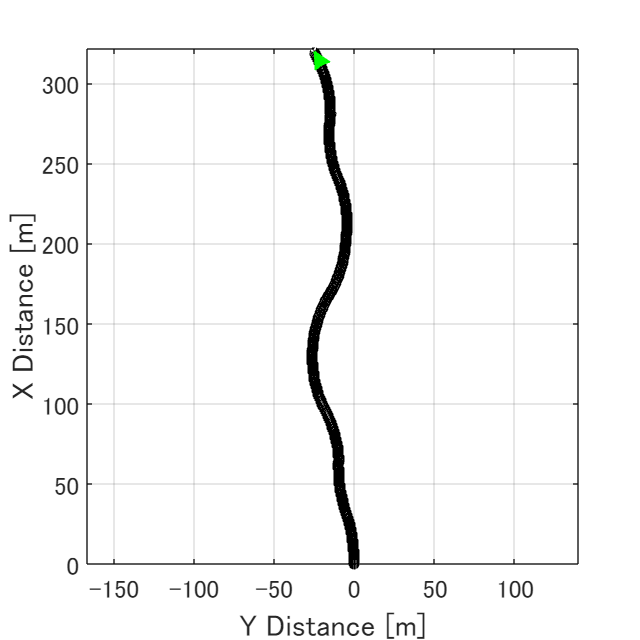

horizon = 16;
horizon_index = 1:horizon;
lmpcObj2.PredictionHorizon = horizon; % 50
lmpcObj2.ControlHorizon = horizon;
Udl = ul0;
Ydl = Cld * xl0;
Xdl = xl0;
DXdl = Ald * xl0 + Bld * [ul0; mdl0] - xl0;

% Update nominal status
lmpcObj2.Model.Nominal = struct('U',Udl,'Y',Ydl,'X',Xdl,'DX',DXdl);

% Constraints
% Steering angle must be within 30 deg.
lmpcObj2.ManipulatedVariables(1).Max = delta_limit * pi / 180;
lmpcObj2.ManipulatedVariables(1).Min = -delta_limit * pi / 180;


% Set optimization weights
lmpcObj2.Weights.OutputVariables = [repmat([0.1, 0.0], horizon-1, 1);
                                  [1, 0]];
lmpcObj2.Weights.ManipulatedVariables = 0.1;

lmpcObj = lmpcObj2;
result_l2 = sim(model_name);

## Figure the tracking error for each.

Confirm that RMSE is smaller for data-driven MPC

However, the maximum error is larger for data-driven MPCs.

rmse
    0.1402



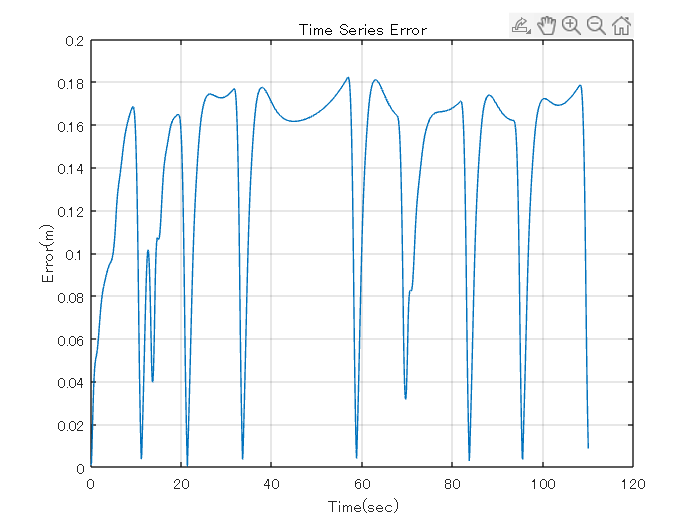

% bicycle model
figure_error(result_l1, ts)

rmse
    0.0880



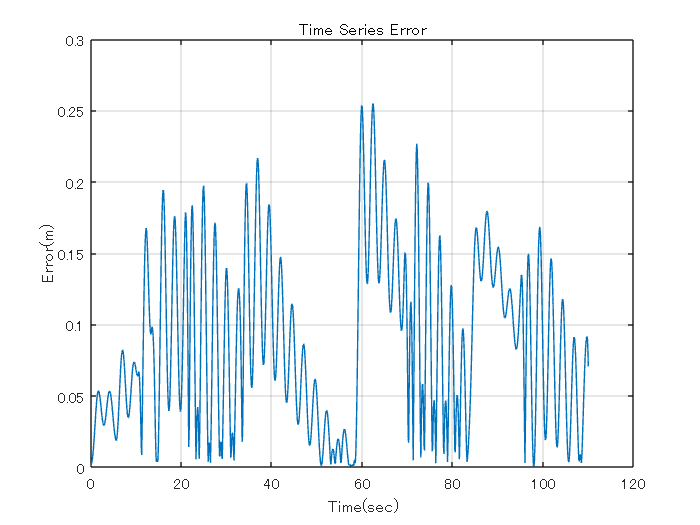

% data driven model
figure_error(result_l2, ts)